%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%PHASE PORTRAIT 

% Data
A = [5,2;-17,-5]; % Case on node
syms x y

% Phase Portrait

detA = det(A)

detA = 9.0000

traA = trace(A)

traA = 0

[eigVecA,eigValA] = eig(A)

eigVecA =   -0.2782 - 0.1669i  -0.2782 + 0.1669i
   0.9459 + 0.0000i   0.9459 + 0.0000i


eigValA =   -0.0000 + 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 - 3.0000i


eigValA = diag(eigValA)

eigValA =   -0.0000 + 3.0000i
  -0.0000 - 3.0000i


parab = traA^2-4*detA;

N = 10; % size of grid
xlin = linspace(-1,1,N); ylin = linspace(-1,1,N);
[Xgrid,Ygrid] = meshgrid(xlin,ylin);

Xgrid_v = Xgrid(:);Ygrid_v = Ygrid(:);
Flowgrid_v = transpose(A*transpose([Xgrid_v,Ygrid_v]));

h1 = figure;hold on;
%plot(Xgrid_v,Ygrid_v,'r.');
quiver(Xgrid_v,Ygrid_v,Flowgrid_v(:,1),Flowgrid_v(:,2))
start_x = linspace(-1, 1, 10);
start_y = linspace(-1, 1, 10);
[start_X, start_Y] = meshgrid(start_x, start_y);
%Lo necesitaremos para las líneas de flujo
u = reshape(Flowgrid_v(:,1), N, N);
v = reshape(Flowgrid_v(:,2), N, N);
title('Phase Portrait');

% Fixed point
fxpts = [0;0];
figure(h1);
plot(fxpts(1),fxpts(2),'o','MarkerFaceColor','r');
% ¿What happend if there is more than one? Plot it using a flag in the
% clasification 
if detA == 0
    disp("There is a line of fixed points---> Infinite amount of fixed points");
    
end

% Straight Trajetories in nodes (eigenvectors)
t = linspace(-1,1);
[~,minI] = min(abs(eigValA));
[~,maxI] = max(abs(eigValA));
strLineMin = t.*eigVecA(:,minI);
strLineMax = t.*eigVecA(:,maxI);
%New trayectories with line of fixed points
if detA == 0
    disp("There is a line of fixed points");
    % Lower eigenvalue
    plot(strLineMin(1,:),strLineMin(2,:),'m');
    plot(strLineMax(1,:),strLineMax(2,:),'g');
    legend("Flow","Fixed point","Slow mannifold", "Fast mannifold", "Flow lines", AutoUpdate= "off");
    for value = -1:0.2:1
        %PLOT THE LINES OF THE LINE OF FIXED POINTS
        NewLineMax = t.*eigVecA(:,maxI) + value;
        plot(NewLineMax(1,:), strLineMax(2,:), "g");
    end

    %HACER INFINITAS LINEAS PARALERLAS
else
    % Lower eigenvalue
    plot(strLineMin(1,:),strLineMin(2,:),'m');
    plot(strLineMax(1,:),strLineMax(2,:),'g');
    % Trazar las líneas de flujo
    streamline(Xgrid, Ygrid, u, v, start_X, start_Y)
    legend("Flow", "Fixed point", "Slow mannifold", "Fast mannifold","Flow lines", AutoUpdate = "off")
end

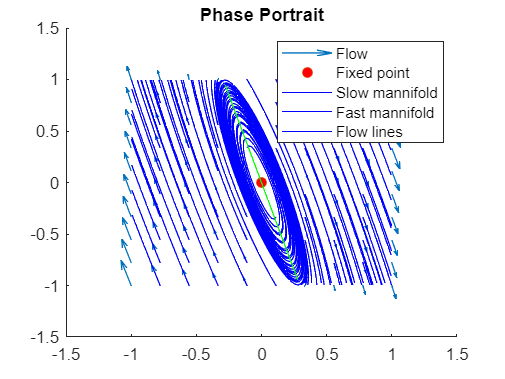


% Plot Trajectories:
t0 = 0; tf = 0.001;
f_lmb = @(t,x) A*x; % lambda function
y0 = [0.5;0.5];
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
plot(ys(:,1),ys(:,2))

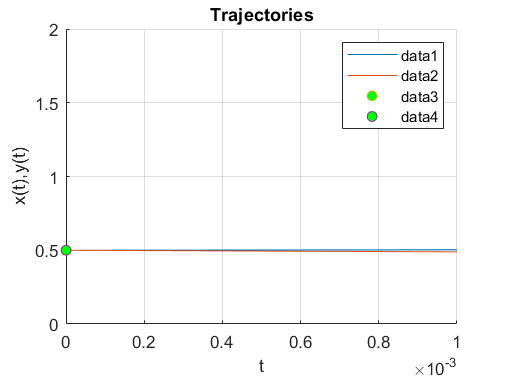


figure;hold on;
plot(ts,ys);plot(0,y0,'o','MarkerFaceColor','g');
axis([t0,tf,0,2])
xlabel('t');ylabel('x(t),y(t)');grid on; title('Trajectories')
legend